## Uge 11 – Torsdag

%  FIR Design: Windowing (Rectangular vs Hamming) + Frequency Sampling
%  Course: 62743 Digital Signal Processing
%  ===============================================================
clear; clc; close all;

%  Image export directory for Obsidian
% ---------------------------------------------------------------
imgDir = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images';
if ~exist(imgDir, 'dir')
    mkdir(imgDir);
end

## Common parameters (Exercise 1)


Fs  = 8000;           % Sampling frequency [Hz]
Fc  = 2000;           % Cutoff for Exercise 1 [Hz]
wc  = 2*pi*Fc/Fs;     % Normalized angular cutoff [rad/sample]

Ntaps1 = 23;          % Number of taps
M1     = Ntaps1 - 1;  % Filter order
K1     = M1/2;        % For odd length: Ntaps1 = 2*K1 + 1
n1     = 0:M1;        % n = 0..22
n1c    = n1 - K1;     % centered: -K1..K1



## Exercise 1-A: Ideal LP via Fourier-transform method (rectangular window)

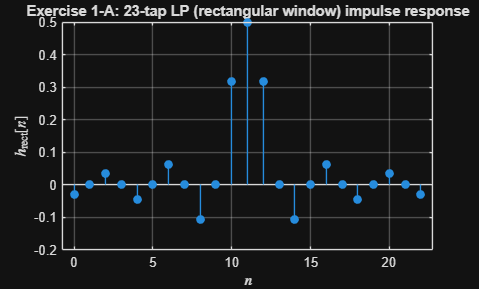

%  Ideal LP impulse response (centered around n=0):
%    h_LP_ideal[n] = sin(wc n)/(pi n), n≠0
%                    wc/pi,            n=0
%  Using MATLAB's normalized sinc:
%    sinc(x) = sin(pi x)/(pi x)
%    h[n] = (wc/pi) * sinc( (wc/pi) * n )

hLP_centered = (wc/pi) * sinc((wc/pi)*n1c);  % ideal LP, infinite-length truncated to -K1..K1

% Causal FIR coefficients (rectangular window = simple truncation)
b_rect = hLP_centered;  % b[n] = h[n-K1], n = 0..M1

% Plot impulse response
figure;
stem(n1, b_rect, 'filled'); grid on;
xlabel('$n$', 'Interpreter', 'latex');
ylabel('$h_{\mathrm{rect}}[n]$', 'Interpreter', 'latex');

title('Exercise 1-A: 23-tap LP (rectangular window) impulse response');

exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Torsdag_1A_rect_impulse.png'), 'Resolution', 300);

## Exercise 1-B: Magnitude vs normalized angular frequency, with ideal LP overlay

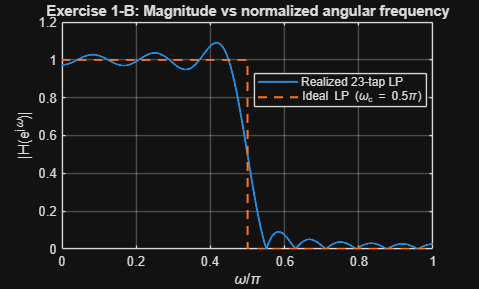

Nw = 2048;
[H_rect, w_rect] = freqz(b_rect, 1, Nw);   % w_rect in [0, \pi]

% Ideal magnitude (brick-wall) low-pass
H_ideal_w = double(w_rect <= wc);

figure;
plot(w_rect/pi, abs(H_rect), 'LineWidth', 1.5); hold on;
plot(w_rect/pi, H_ideal_w, '--', 'LineWidth', 1.5);
grid on;
xlabel('\omega/\pi'); ylabel('|H(e^{j\omega})|');
title('Exercise 1-B: Magnitude vs normalized angular frequency');
legend('Realized 23-tap LP', 'Ideal LP (\omega_c = 0.5\pi)', 'Location','best');

exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Torsdag_1B_mag_norm.png'), 'Resolution', 300);

## Exercise 1-C:  Frequency axis in Hz + log magnitude and first side-lobe

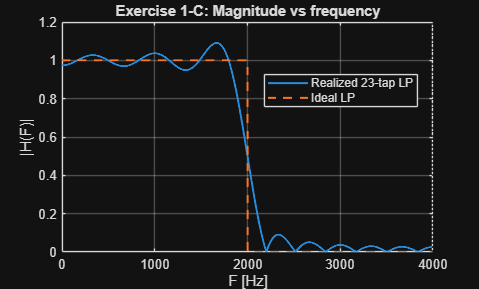

F = w_rect*Fs/(2*pi);   % F [Hz] from normalized angular frequency

% Magnitude vs frequency
figure;
plot(F, abs(H_rect), 'LineWidth', 1.5); hold on;
plot(F, double(w_rect <= wc), '--', 'LineWidth', 1.5);
grid on;
xlabel('F [Hz]'); ylabel('|H(F)|');
title('Exercise 1-C: Magnitude vs frequency');
xline(Fs/2, ':k', 'F_s/2');
legend('Realized 23-tap LP', 'Ideal LP', 'Location','best');

exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Torsdag_1C_mag_Hz.png'), 'Resolution', 300);


% Log-magnitude in dB
HdB_rect = 20*log10(abs(H_rect)+eps);

figure;
plot(F, HdB_rect, 'LineWidth', 1.5); grid on;
xlabel('F [Hz]');
ylabel('H_{dB}(F) [dB]');  

title('Exercise 1-C: Log-magnitude (rectangular window)');

% Optional: crude estimate of first stopband peak (side-lobe)
idx_sb = find(F > Fc);             % stopband indices
[peak_sb, idx_local] = max(HdB_rect(idx_sb));
F_peak = F(idx_sb(idx_local));
fprintf('Exercise 1-C: first stopband peak ~ %.2f dB at F ≈ %.1f Hz (rectangular)\n', ...
        peak_sb, F_peak);

Exercise 1-C: first stopband peak ~ -6.12 dB at F ≈ 2002.0 Hz (rectangular)


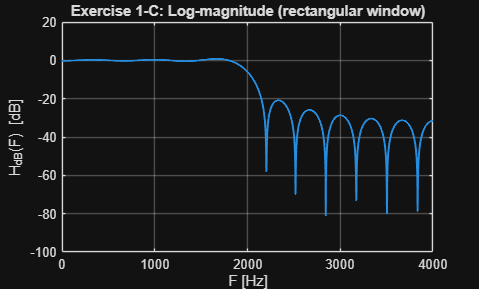


exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Torsdag_1C_logmag_rect.png'), 'Resolution', 300);

## Exercise 1-D and 1-E: Hamming window definition + coefficients and stem plot

% Hamming window:
%   w_Ham[n] = 0.54 - 0.46 cos(2\pi n / M1),  n = 0..M1
wHam_manual  = 0.54 - 0.46*cos(2*pi*n1/M1);

% (Optional check vs built-in hamming)
wHam_builtin = hamming(Ntaps1).';     % row vector
fprintf('Max diff between manual and built-in Hamming: %.2e\n', ...
        max(abs(wHam_manual - wHam_builtin)));

Max diff between manual and built-in Hamming: 3.33e-16


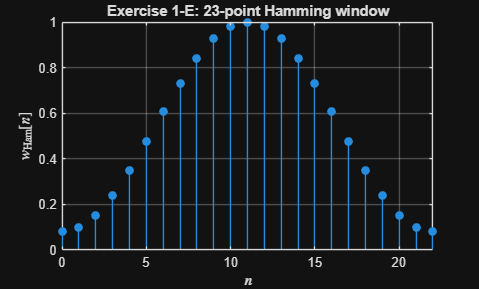


figure;
stem(n1, wHam_manual, 'filled'); grid on;
xlabel('$n$', 'Interpreter', 'latex');
ylabel('$w_{\mathrm{Ham}}[n]$', 'Interpreter', 'latex');

title('Exercise 1-E: 23-point Hamming window');
xlim([0 M1]);   % min = 0, max = 22
exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Torsdag_1E_hamming_window.png'), 'Resolution', 300);

## Exercise 1-F:

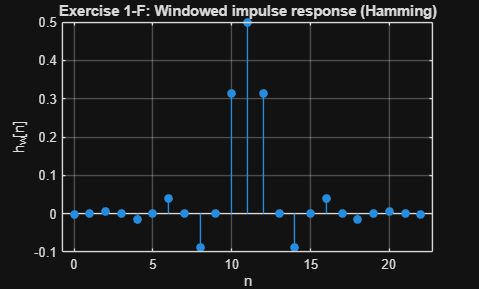

%  Windowed FIR coefficients: h_w[n] = h_LP[n-K1] * w_Ham[n]

h_w = b_rect .* wHam_manual;     % element-wise product

figure;
stem(n1, h_w, 'filled'); grid on;
xlabel('n'); ylabel('h_w[n]');
title('Exercise 1-F: Windowed impulse response (Hamming)');

exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Torsdag_1F_impulse_hamming.png'), 'Resolution', 300);

## Exercise 1-G: Compare log-magnitude (rectangular vs Hamming)

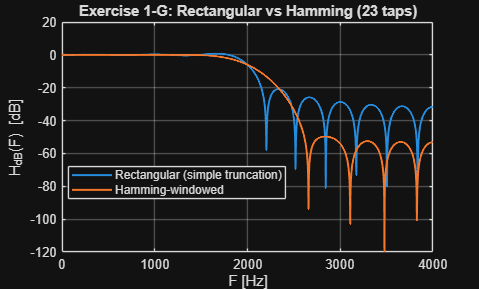

[H_ham, ~] = freqz(h_w, 1, w_rect);  % reuse w_rect grid
HdB_ham = 20*log10(abs(H_ham)+eps);

figure;
plot(F, HdB_rect, 'LineWidth', 1.5); hold on;
plot(F, HdB_ham, 'LineWidth', 1.5);
grid on;
xlabel('F [Hz]');
ylabel('H_{dB}(F) [dB]');   


title('Exercise 1-G: Rectangular vs Hamming (23 taps)');
legend('Rectangular (simple truncation)', 'Hamming-windowed', 'Location','best');

exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Torsdag_1G_logmag_rect_vs_hamming.png'), 'Resolution', 300);


% Optional: approximate first stopband peaks
idx_sb2 = find(F > Fc);
[peak_rect, iR] = max(HdB_rect(idx_sb2));
[peak_ham,  iH] = max(HdB_ham(idx_sb2));
fprintf('Rectangular window: first visible stopband peak ~ %.2f dB\n', peak_rect);

Rectangular window: first visible stopband peak ~ -6.12 dB


fprintf('Hamming window:    first visible stopband peak ~ %.2f dB\n', peak_ham);

Hamming window:    first visible stopband peak ~ -6.07 dB


## Exercise 2:

%  Frequency sampling design of 7-tap LP with cutoff \omega_c = 0.3\pi

wc2   = 0.3*pi;   % cutoff (rad/sample)
K2    = 3;        % from N_taps = 2K2+1=7
M2    = 2*K2;     % filter order
Ntaps2 = M2 + 1;  % 7 taps


## 2-B) Sampled frequencies

k = 0:K2;
wk = 2*pi*k/(M2+1);   % \omega_k = 2\pi k/(M+1)


## 2-C) Check which are in passband (wk <= wc2)

in_pass = wk <= wc2;


## 2-D) Ideal magnitude samples H[k] for a low-pass:

Hk = double(in_pass);   % 1 in passband, 0 in stopband


## 2-E) Coefficients b[n] for n = 0..K2 via:

%   b[n] = (1/(2K2+1)) [ H[0] + 2 sum_{k=1..K2} H[k] cos(2\pi k (n-K2)/(2K2+1)) ]
n_left = 0:K2;
b_left = zeros(size(n_left));

for ii = 1:length(n_left)
    n = n_left(ii);
    % inner sum over k = 1..K2
    k_vec = 1:K2;
    inner = sum( Hk(2:end) .* cos(2*pi*k_vec*(n-K2)/(2*K2+1)) );
    b_left(ii) = (1/(2*K2+1)) * ( Hk(1) + 2*inner );
end


## 2-F) Use symmetry (Type I linear-phase) to get full 7-tap coefficients

b2 = zeros(1, Ntaps2);
b2(1:K2+1)        = b_left;          % n = 0..3
b2(Ntaps2:-1:K2+2) = b_left(1:K2);   % mirror n = 4..6

fprintf('\nExercise 2: 7-tap LP (frequency sampling)\n');


Exercise 2: 7-tap LP (frequency sampling)


fprintf('w_k/pi = ['); fprintf(' %.4f', wk/pi); fprintf(' ]\n');

w_k/pi = [ 0.0000 0.2857 0.5714 0.8571 ]


fprintf('H[k]   = ['); fprintf(' %.1f', Hk); fprintf(' ]\n');

H[k]   = [ 1.0 1.0 0.0 0.0 ]


fprintf('b2     = ['); fprintf(' %.4f', b2); fprintf(' ]\n\n');

b2     = [ -0.1146 0.0793 0.3210 0.4286 0.3210 0.0793 -0.1146 ]



## 2-H) Frequency response

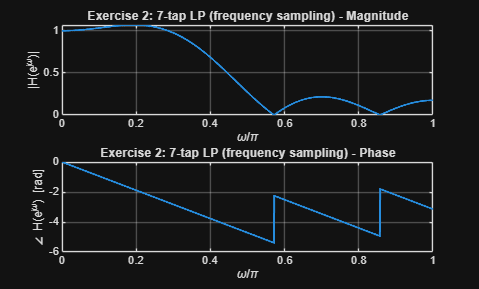

Nw2 = 2048;
[H2, w2] = freqz(b2, 1, Nw2);
HdB2 = 20*log10(abs(H2)+eps);

figure;
subplot(2,1,1);
plot(w2/pi, abs(H2), 'LineWidth', 1.5); grid on;
xlabel('\omega/\pi'); ylabel('|H(e^{j\omega})|');
title('Exercise 2: 7-tap LP (frequency sampling) - Magnitude');

subplot(2,1,2);
plot(w2/pi, unwrap(angle(H2)), 'LineWidth', 1.5); grid on;
xlabel('\omega/\pi'); ylabel('\angle H(e^{j\omega}) [rad]');
title('Exercise 2: 7-tap LP (frequency sampling) - Phase');

exportgraphics(gcf, fullfile(imgDir, 'DSP_U11_Torsdag_2H_freqsampling_mag_phase.png'), 'Resolution', 300);